# Example: Creating a Pyramidal Cell

## Create soma and main axon

cell = ELFENN.Cell('cell');

soma = ELFENN.Section('soma', ...
    'radius', 16.81/2,...
    'sectionGeometry', 'S', ...
    'nSeg', 1,...
    'sectionLength', 16.81);

axon_main = ELFENN.Section('axon-main-1', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 75);


cell.connectsection(soma, axon_main, [0,0,0]);

axon_branch = ELFENN.Section('axon-branch-1', ...
    'radius', 1,...
    'nSeg',5,...
    'sectionLength', 75);

cell.connectsection(axon_main, axon_branch);
cell.rotatechunk('axon-branch-1', [0,0,-1.1]);

axon_branch = ELFENN.Section('axon-branch-2', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 75);

cell.connectsection(axon_main, axon_branch);
cell.rotatechunk('axon-branch-2', [0,0,1.2]);

axon_main_copy = ELFENN.Section('axon-main-2', ...
    'radius', 1,...
    'nSeg', 17,...
    'sectionLength', 315);

cell.connectsection(axon_main, axon_main_copy);
axon_main = axon_main_copy;

axon_branch = ELFENN.Section('axon-branch-3', ...
    'radius', 1,...
    'nSeg', 9,...
    'sectionLength', 150);

cell.connectsection(axon_main, axon_branch);
cell.rotatechunk('axon-branch-3', [0,0,pi/6]);

axon_main_copy = ELFENN.Section('axon-main-3', ...
    'radius', 1,...
    'nSeg', 19,...
    'sectionLength', 350);

cell.connectsection(axon_main, axon_main_copy);
axon_main = axon_main_copy;

axon_main_copy = ELFENN.Section('axon-main-4', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 80);

cell.connectsection(axon_main, axon_main_copy);
axon_main = axon_main_copy;

axon_main_copy = ELFENN.Section('axon-main-5', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 80);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-5', [0,0,0.3]);
axon_main = axon_main_copy;


axon_branch = ELFENN.Section('axon-branch-4', ...
    'radius', 1,...
    'nSeg', 3,...
    'sectionLength', 60);

cell.connectsection(axon_main, axon_branch);
cell.rotatechunk('axon-branch-4', [0,0,-pi/4]);

axon_main = cell.getsectionbyname('axon-main-3');
axon_branch = ELFENN.Section('axon-branch-5', ...
    'radius', 1,...
    'nSeg', 3,...
    'sectionLength', 30);
cell.connectsection(axon_main, axon_branch);
cell.rotatechunk('axon-branch-5', [0,0,-0.4]);

axon_main = axon_branch;
axon_branch = ELFENN.Section('axon-branch-6', ...
    'radius', 1,...
    'nSeg', 3,...
    'sectionLength', 60);
cell.connectsection(axon_main, axon_branch);
cell.rotatechunk('axon-branch-6', [0,0,0.05]);

axon_main = axon_branch;
axon_branch = ELFENN.Section('axon-branch-7', ...
    'radius', 1,...
    'nSeg', 3,...
    'sectionLength', 50);
cell.connectsection(axon_main, axon_branch);
cell.rotatechunk('axon-branch-7', [0,0,-pi/4]);

axon_main = axon_branch;
axon_main_copy = ELFENN.Section('axon-branch-8', ...
    'radius', 1,...
    'nSeg', 3,...
    'sectionLength', 50);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-branch-8', [0,0,-pi/4]);

axon_main_copy = ELFENN.Section('axon-branch-9', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 75);
cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-branch-9', [0,0,0]);

axon_main = cell.getsectionbyname('axon-main-5');
axon_main_copy = ELFENN.Section('axon-branch-10', ...
    'radius', 1,...
    'nSeg', 3,...
    'sectionLength', 50);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-branch-10', [0,0,0.3]);

## Add dendrites (for simplicity these are randomly oriented)

nDend = 15;
for i = 1:nDend
    somaAngle = rand(3,1) - 0.5;
    somaAngle = 2*pi*somaAngle;
    L = 200*rand(1,1);
    
    nSeg = 1;
    dend = ELFENN.Section(['dend-' num2str(i)], ...
        'radius', 1,...
        'nSeg', nSeg ,...
        'sectionLength', L);
    cell.connectsection(soma, dend, somaAngle);
end

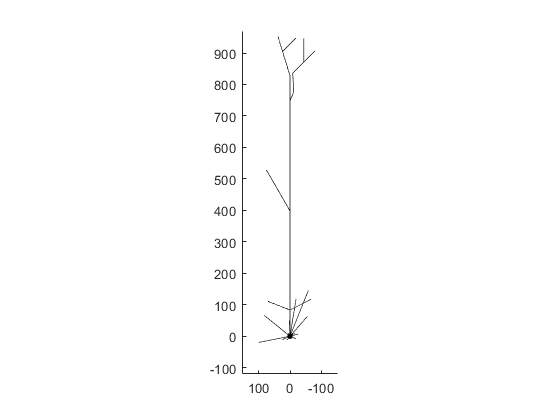


cell.rotateoffsoma('soma');

figure
plotcell(cell);
daspect([1,1,1])
view([-90, 90])
xlim([-120, 970]);
ylim([-150, 150]);